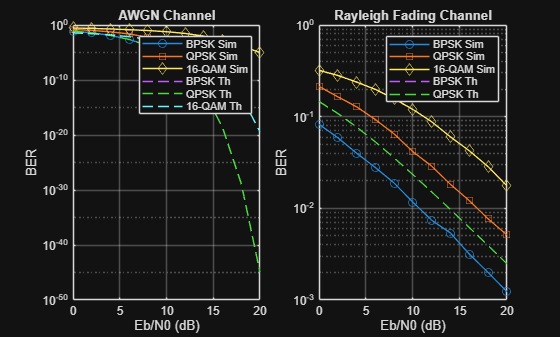

clc; clear; close all;

% Parameters
N = 1e5;                 % Number of bits
EbN0_dB = 0:2:20;        % SNR range
EbN0 = 10.^(EbN0_dB/10);

% Preallocate BER arrays
ber_bpsk_awgn = zeros(size(EbN0));
ber_qpsk_awgn = zeros(size(EbN0));
ber_qam_awgn  = zeros(size(EbN0));

ber_bpsk_rayleigh = zeros(size(EbN0));
ber_qpsk_rayleigh = zeros(size(EbN0));
ber_qam_rayleigh  = zeros(size(EbN0));

% Generate random bits
bits = randi([0 1], N, 1);

%% ================= BPSK =================
bpsk_mod = 2*bits - 1;

for i = 1:length(EbN0)
    % Noise
    noise = sqrt(1/(2*EbN0(i))) * randn(N,1);
    
    %% AWGN
    rx = bpsk_mod + noise;
    bits_hat = rx > 0;
    ber_bpsk_awgn(i) = sum(bits ~= bits_hat)/N;
    
    %% Rayleigh Fading
    h = (randn(N,1) + 1j*randn(N,1))/sqrt(2);
    rx_fade = h .* bpsk_mod + noise;
    rx_eq = rx_fade ./ h; % Equalization
    bits_hat = real(rx_eq) > 0;
    ber_bpsk_rayleigh(i) = sum(bits ~= bits_hat)/N;
end

%% ================= QPSK =================
bits_qpsk = reshape(bits(1:floor(N/2)*2), [], 2);

symbols = (2*bits_qpsk(:,1)-1) + 1j*(2*bits_qpsk(:,2)-1);
symbols = symbols / sqrt(2);

for i = 1:length(EbN0)
    noise = sqrt(1/(2*EbN0(i))) * (randn(size(symbols)) + 1j*randn(size(symbols)));
    
    %% AWGN
    rx = symbols + noise;
    bits_hat = [real(rx)>0 imag(rx)>0];
    ber_qpsk_awgn(i) = sum(bits_qpsk(:) ~= bits_hat(:))/numel(bits_qpsk);
    
    %% Rayleigh
    h = (randn(size(symbols)) + 1j*randn(size(symbols)))/sqrt(2);
    rx_fade = h .* symbols + noise;
    rx_eq = rx_fade ./ h;
    bits_hat = [real(rx_eq)>0 imag(rx_eq)>0];
    ber_qpsk_rayleigh(i) = sum(bits_qpsk(:) ~= bits_hat(:))/numel(bits_qpsk);
end

%% ================= 16-QAM =================
M = 16;
k = log2(M);

bits_qam = bits(1:floor(N/k)*k);
symbols = qammod(bits_qam, M, 'InputType', 'bit', 'UnitAveragePower', true);

for i = 1:length(EbN0)
    noise = sqrt(1/(2*EbN0(i))) * (randn(size(symbols)) + 1j*randn(size(symbols)));
    
    %% AWGN
    rx = symbols + noise;
    bits_hat = qamdemod(rx, M, 'OutputType', 'bit', 'UnitAveragePower', true);
    ber_qam_awgn(i) = sum(bits_qam ~= bits_hat)/length(bits_qam);
    
    %% Rayleigh
    h = (randn(size(symbols)) + 1j*randn(size(symbols)))/sqrt(2);
    rx_fade = h .* symbols + noise;
    rx_eq = rx_fade ./ h;
    bits_hat = qamdemod(rx_eq, M, 'OutputType', 'bit', 'UnitAveragePower', true);
    ber_qam_rayleigh(i) = sum(bits_qam ~= bits_hat)/length(bits_qam);
end

%% ================= Theoretical BER =================

% AWGN
theory_bpsk = 0.5*erfc(sqrt(EbN0));
theory_qpsk = 0.5*erfc(sqrt(EbN0));
theory_qam  = (3/(2*(M-1))) * erfc(sqrt((3*k*EbN0)/(2*(M-1))));

% Rayleigh
theory_bpsk_rayleigh = 0.5*(1 - sqrt(EbN0./(1+EbN0)));
theory_qpsk_rayleigh = theory_bpsk_rayleigh;

%% ================= Plot =================
figure;

% AWGN
subplot(1,2,1);
semilogy(EbN0_dB, ber_bpsk_awgn, 'o-', ...
         EbN0_dB, ber_qpsk_awgn, 's-', ...
         EbN0_dB, ber_qam_awgn, 'd-', ...
         EbN0_dB, theory_bpsk, '--', ...
         EbN0_dB, theory_qpsk, '--', ...
         EbN0_dB, theory_qam, '--');
grid on;
xlabel('Eb/N0 (dB)');
ylabel('BER');
title('AWGN Channel');
legend('BPSK Sim','QPSK Sim','16-QAM Sim','BPSK Th','QPSK Th','16-QAM Th');

% Rayleigh
subplot(1,2,2);
semilogy(EbN0_dB, ber_bpsk_rayleigh, 'o-', ...
         EbN0_dB, ber_qpsk_rayleigh, 's-', ...
         EbN0_dB, ber_qam_rayleigh, 'd-', ...
         EbN0_dB, theory_bpsk_rayleigh, '--', ...
         EbN0_dB, theory_qpsk_rayleigh, '--');
grid on;
xlabel('Eb/N0 (dB)');
ylabel('BER');
title('Rayleigh Fading Channel');
legend('BPSK Sim','QPSK Sim','16-QAM Sim','BPSK Th','QPSK Th');